# Find farfield E polaristion

We cand determine the topological charge of a resonance by looking at how the polarisation of the E field changes as we follow a path anticlockwise around the resonance.  ie, we set theta to say 0.2 deg. and then vary phi from o to 90 degrees.  By the symmetry of the resonator we can infer what the polarisation from 90 to 360 will be and then calculate the topological charge:  Positive charge if the polarisation rotates in the same direction as the path; the numerical value is equal to the number of rotations.

clear;
extra_options = matthew_extra_options(options);


File name.


fname_prefix = [options.cut_plane_dir 'ghost_dimer_110_SFG_paper_cut_plane_'];

num_frequencies = options.num_freqs;
num_thetas = options.num_thetas;

Effx = zeros(1,num_thetas);
Effy = zeros(1,num_thetas);
Effz = zeros(1,num_thetas);
Hffx = zeros(1,num_thetas);
Hffy = zeros(1,num_thetas);
Hffz = zeros(1,num_thetas);

% num_frequencies,  num_thetas, x/y/z, NF/FF

Do the FFT on both Near field and Farfield cut planes.

for cut_plane_index = 1:length(options.cut_plane)
    for direction = options.direction
    

The file columns are: x, y and then ind=1, theta=0: Ex, Ey Ez; ind=2, theta=0: Ex, Ey, Ez;...

        %freq_num = [25 24 24 23 22 22]
        for theta_num=options.plot_theta_nums
            freq_num = options.plot_freq_nums(theta_num);
            cut_plane_data = matthew_get_cut_plane_fields(extra_options, options.cut_plane(cut_plane_index), direction, theta_num);
            
        
            [FTx, FTy, FTz,FThx, FThy, FThz,~] = matthew_create_fft_of_cut_plane(cut_plane_data, freq_num);
            
            zeroth_order_ind = length(FTx)/2+1;
               
            Effx(theta_num) = FTx(zeroth_order_ind, zeroth_order_ind);
            Effy(theta_num) = FTy(zeroth_order_ind, zeroth_order_ind);
            Effz(theta_num) = FTz(zeroth_order_ind, zeroth_order_ind);
            Hffx(theta_num) = FThx(zeroth_order_ind, zeroth_order_ind);
            Hffy(theta_num) = FThy(zeroth_order_ind, zeroth_order_ind);
            Hffz(theta_num) = FThz(zeroth_order_ind, zeroth_order_ind);
            
            datax = cut_plane_data.Ex(:,freq_num);
            datay = cut_plane_data.Ey(:,freq_num);
            dataz = cut_plane_data.Ez(:,freq_num);
        
            num_x_values = length(unique(cut_plane_data.x));
            Ex = flipud(vec2mat(datax, num_x_values));
            Ey = flipud(vec2mat(datay, num_x_values));
            Ez = flipud(vec2mat(dataz, num_x_values));
            
            [X,Y] = meshgrid(unique(cut_plane_data.x), unique(cut_plane_data.y));
            Ex = Ex(1:4:end,1:4:end);
            Ey = Ey(1:4:end,1:4:end);
            Ez = Ez(1:4:end,1:4:end);
            X = X(1:4:end,1:4:end);
            Y = Y(1:4:end,1:4:end);
            figure;
            quiver(X,Y,Ex,Ey);
            title(['E_x and E_y with \theta=' num2str(options.thetas(theta_num))]);
            
            datax = cut_plane_data.Hx(:,freq_num);
            datay = cut_plane_data.Hy(:,freq_num);
            dataz = cut_plane_data.Hz(:,freq_num);
        
            Hx = flipud(vec2mat(datax, num_x_values));
            Hy = flipud(vec2mat(datay, num_x_values));
            Hz = flipud(vec2mat(dataz, num_x_values));
            
            Hx = Hx(1:4:end,1:4:end);
            Hy = Hy(1:4:end,1:4:end);
            Hz = Hz(1:4:end,1:4:end);
            %{
            figure;
            quiver(X,Y,Hx,Hy);
            title(['H_x and H_y with \theta=' num2str(options.thetas(theta_num))]);
            %}
            %{
            datax = cut_plane_data.polx(:,freq_num);
            datay = cut_plane_data.poly(:,freq_num);
            dataz = cut_plane_data.polz(:,freq_num);
                        
            polx = flipud(vec2mat(datax, num_x_values));
            poly = flipud(vec2mat(datay, num_x_values));
            polz = flipud(vec2mat(dataz, num_x_values));
            
            polx = polx(1:4:end,1:4:end);
            poly = poly(1:4:end,1:4:end);
            polz = polz(1:4:end,1:4:end);
            %}
            %{
            figure;
            quiver(X,Y,polx,poly);
            title(['pol_x and pol_y with \theta=' num2str(options.thetas(theta_num))]);
            %}

Not plots or file saving, just extract the zeroth order Fourier component.       

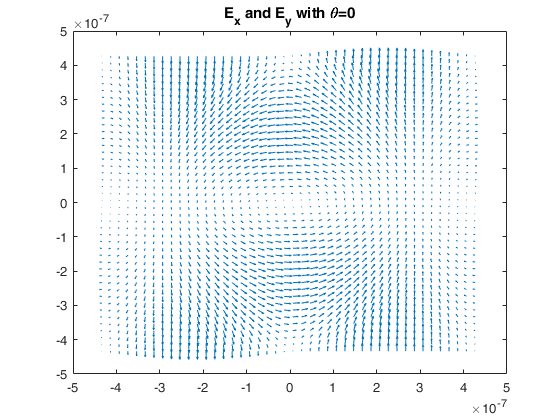

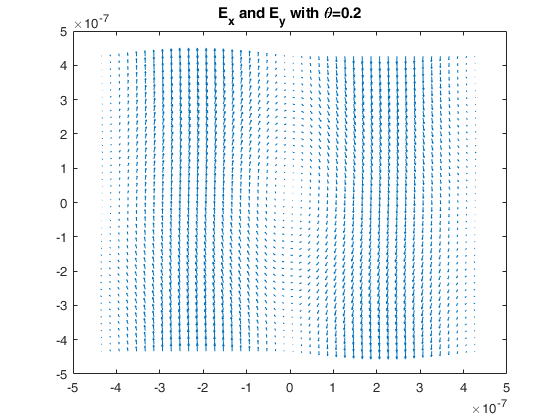

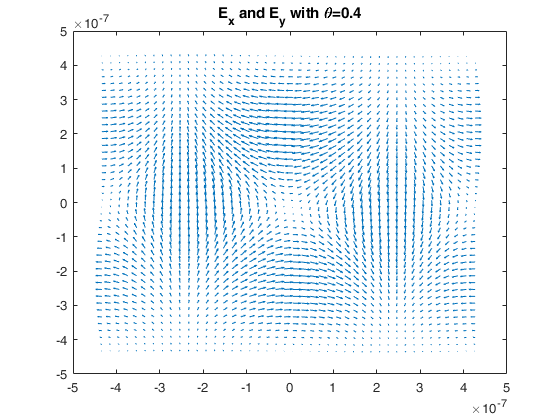

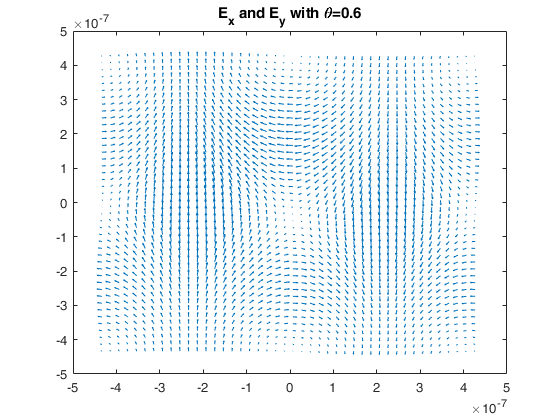

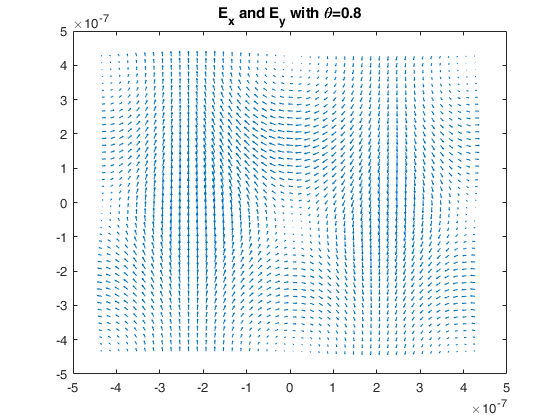

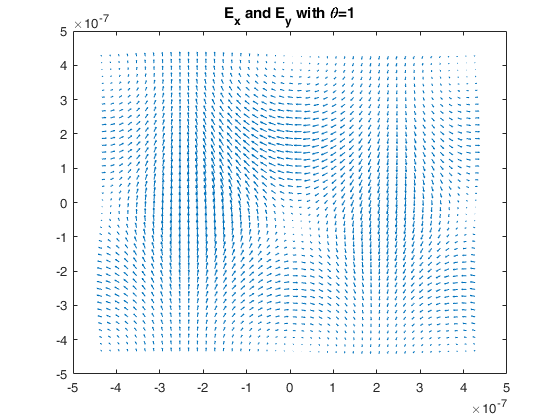

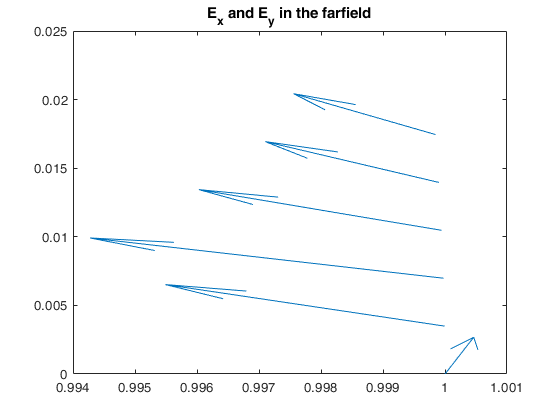

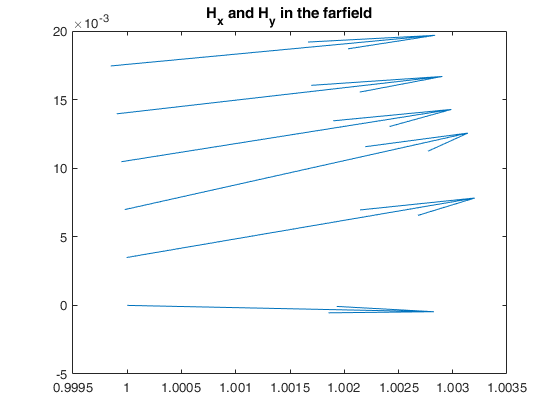

        end
        figure;
        x = cosd(options.thetas);
        y = sind(options.thetas);
        
        quiver(x,y,Effx,Effy);
        title('E_x and E_y in the farfield');
        
        figure;
        quiver(x,y,Hffx,Hffy);
        title('H_x and H_y in the farfield');
    end
end

If this script is being run by another script then delete all of the temporary variables.

if exist('no_plotting', 'var') == 1
    clear fname dat num_x_values datx daty datz Ix Iy Iz cut_plane cut_plane_index;
    clear data_raw fname_prefix fname_suffix FTx FTy FTz i ii zeroth_order_ind;
    clear freq_num save_to_file theta_num;
end